# Thevenin Battery Model

### Parameters

load('batteryModel.mat');

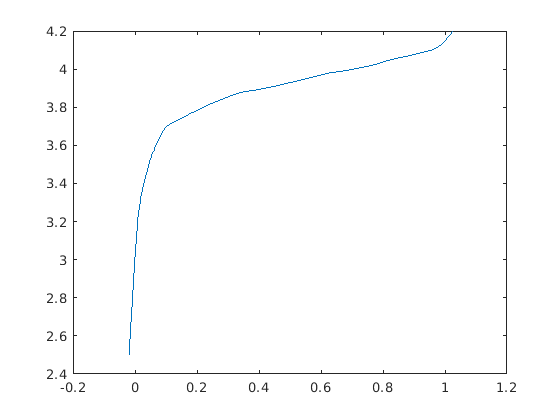

v = 2.5:.01:4.2;
T = 25;
plot(SOCfromOCVtemp(v,T,battery), v);


Q   = ; % total capacity in mAh
n   =  .99; % coulombic efficiency
M   = .002002; % dynamic hysteresis volts factor
Mo  = .002354; % instant hysteresis volts factor
Ro  = .002; % internal resistance
R   =  [1, 2, 3]; % diffusion / warburg impedence, pairs with C
C   =  [9, 8, 7]; % diffusion / warburg impedence, pairs with R
g   = .01;  % gamma, tunes decay in hysteresis
dt  = .001; % delta t
load('soc_ocv.mat'); % soc-ocv relationship

### State Variables

z   = state of charge (SOC)

        z[k+1] = z[k] - n[k]*dt*Io[k]

Ir  = current vector through each resistor in R

        Ir[k+1] = Arc*Ir[k] + Brc*Io[k]

h  = hysteresis

        h[k+1] = H[k]*h[k] + (H[k]-1)*sign(Io[k])

### Intermediates

if length(R) ~= length(C)
    error("R and C must be the same length");
end

- Arc, 'A' matrix of the state equation for Ir 

Arc = zeros(length(R));
for i = 1:length(R)
    Arc(i,i) = exp(-dt/(R(i)*C(i)));
end

- Brc, 'B' matrix of the state equation for Ir

Brc = zeros(length(R), 1);
for i = 1:length(R)
    Brc(i,1) = 1 - exp(-dt/(R(i)*C(i)));
end

- H, 'A' matrix (H-1 is 'B' matrix) of state equation for h, H is dynamic!

k = 1; % timestep
Io = .1; % current at time k
H(k) = exp(-abs((n(k)*Io(k)*g*dt)/Q))

H = 1.0000

### State equations

z = 1.0; % soc
Ir = ones(length(R), 1);
h = 1.0;

z_dot = z -(n*dt)/Q*Io;
Ir_dot = Arc*Ir + Brc*Io;
h_dot = H*h + (H-1)*sign(Io);

### Output equations

T = 25.0; % temperature of battery in celcius
S = sign(Io); %TODO should be a function, 0 else sign change
V = soc_ocv(z*100) + Mo*S + M*h - sum(R*Ir) - Ro*Io;

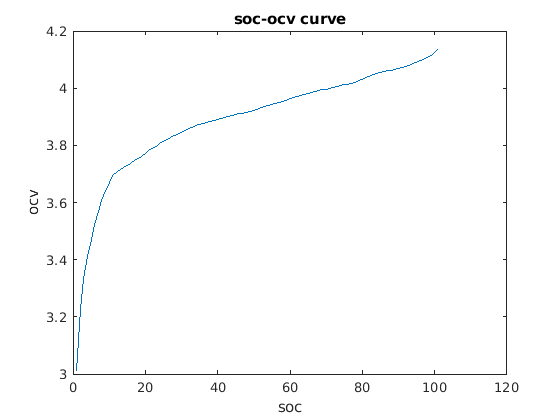

f1 = figure(1); clf;
plot(soc_ocv);
title("soc-ocv curve");
xlabel("soc");
ylabel("ocv");

soc_ocv(31)

ans = 3.8514

Y = zeros(50,1);
A = zeros(50,3);
for i=1:50
    a = randi([-10 10],1,3);
    A(i,:) = a;
    Y(i) = f(a);
end





function y = f(A)
    y = 4*A(1) + 2*A(2) - 6*A(3);

end



